# SIMPLE GAS TURBINE

clear
air = GRI30;
X_h20 = rh2P(0.5, 298.15)/oneatm

X_h20 = 0.0156

air_comp = 'N2:0.757223,O2:0.202157,H2O:0.0155,Ar:0.009015,CO2:0.000397';
set(air, "T", 298.15, "P", oneatm, "X", air_comp);
x_1 = flowExergy_mass(air);
fuel = GRI30;
fuel_comp = 'CH4:0.907,C2H6:0.036,C3H8:0.019,N2:0.018,CO2:0.01,O2:0.01';
set(fuel, "T", 298.15, "P", oneatm, "X", fuel_comp);
h_fuel = enthalpy_mass(fuel);
lhv_fuel = LHV_mass(fuel);
x_fuel = flowExergy_mass(fuel);

m_air = 24;
eta_comp = 0.9;
eta_turb = 0.88;
compression_ratio = 23;
p4 = oneatm;

% Compressor
h1 = enthalpy_mass(air);
p1 = oneatm;
p2 = p1*compression_ratio; 
t1 = temperature(air);
[comp_w, t2] = pump_work(eta_comp, p1, p2, t1);
set(air, "P", p2, "T", t2);
h2 = temperature(air);
x_2 = flowExergy_mass(air);

% Combustor
mix = GRI30;
xMix = (m_air*moleFractions(air) + moleFractions(fuel) )./(m_air+1);
set(mix, "P", p2, "T", t2, "X", xMix); % Assume ideal mixture
equilibrate(mix, 'HP'); % Assume fuel is added at temperature T2
p3 = p2*0.95; % 5% pressure drop over combustor
set(mix, "P", p3);
h3 = enthalpy_mass(mix);
t3 = temperature(mix);
x_3 = flowExergy_mass(mix);

%Turbine
[turb_w, t4] = turb_work(eta_turb, p3, p4, t3);
set(mix, "P", p4, "T", t4)
h4 = enthalpy_mass(mix);
x_4 = flowExergy_mass(mix);

net_w = -(turb_w+comp_w);

first_law_eff = net_w/lhv_fuel

first_law_eff = 0.1374

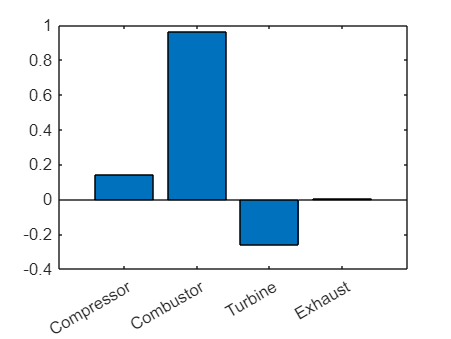


x_in = x_fuel + x_1 + comp_w;
x_out = x_4 + abs(turb_w);
x_des = x_in - net_w;
X = categorical({'Compressor', 'Combustor', 'Turbine', 'Exhaust'});
X = reordercats(X,{'Compressor', 'Combustor', 'Turbine', 'Exhaust'});
bar(X, [x_1+comp_w-x_2, x_2+x_fuel-x_3, x_3-x_4+turb_w, x_4]./x_des)

function P_h2o = rh2P(rh, T)
    w = Water; set(w, "T", T);
    setState_satVapor(w);
    P_h2o = rh*pressure(w);
end

function [total_w, T] = turb_work(eta, Pin, Pout, Tin)
    w = GRI30;
    set(w, "T", Tin, "P", Pin) % Initial Conditions of water
    n = 100; % discretization points for pressure
    h = (Pout-Pin)/n; % integration step
    total_w = 0; % total work output of turbine
    for p = Pin+h:h:Pout
        h1 = enthalpy_mass(w);
        s0 = entropy_mass(w);
        setState_SP(w, [s0, p]) % isentropic expansion
        h2 = enthalpy_mass(w);
        dw_s = h2-h1; % isentropic work
    
        dw = dw_s*eta; % actual work
        setState_HP(w, [h1+dw, p]) % actual new state of steam 
        total_w = total_w + dw; % sum all steps
    end
    T = temperature(w);
end

function [total_w, T] = pump_work(eta, Pin, Pout, Tin)
    w = GRI30;
    set(w, "T", Tin, "P", Pin) % Initial Conditions of water
    n = 100; % discretization points for pressure
    h = (Pout-Pin)/n; % integration step
    total_w = 0; % total work output of turbine
    for p = Pin+h:h:Pout
        h1 = enthalpy_mass(w);
        s0 = entropy_mass(w);
        setState_SP(w, [s0, p]) % isentropic expansion
        h2 = enthalpy_mass(w);
        dw_s = h2-h1; % isentropic work
    
        dw = dw_s/eta; % actual work
        setState_HP(w, [h1+dw, p]) % actual new state of steam 
        total_w = total_w + dw; % sum all steps
    end
    T = temperature(w);
end

function hhv = HHV_mass(gas)
    T0 = 298.15;
    P0 = oneatm;
    % [ C, H, N, O, Ar]
    mm_all = molecularWeights(gas);
    mm = [mm_all(speciesIndex(gas,'C')), mm_all(speciesIndex(gas,'H')), mm_all(speciesIndex(gas,'N')), mm_all(speciesIndex(gas,'O')), mm_all(speciesIndex(gas,'Ar'))]; % molar masses (g/mol)
    mass_frac = [ elementalMassFraction(gas,'C'),  elementalMassFraction(gas,'H'),  elementalMassFraction(gas,'N'), elementalMassFraction(gas,'O'),  elementalMassFraction(gas,'Ar')];
    mole_frac = (mass_frac./mm)./(sum(mass_frac./mm)); % normalize to 1mol of elements
    avg_atoms = meanMolecularWeight(gas)/sum(mm.*mole_frac); % average atoms per molecule
    comb_frac = mole_frac*avg_atoms; % atoms of each element from combusting a mole of input gas

    % Assign Inputs and Outputs
    n_out_co2 = comb_frac(1);
    n_out_h20 = comb_frac(2)/2;
    n_in_o2 = max(n_out_h20/2 + n_out_co2 - (comb_frac(4)/2), 0);
    n_out_o2 = max((comb_frac(4)/2) - n_out_h20/2 - n_out_co2 , 0);
    n_in_n2 = 3.76*n_in_o2;
    n_out_n2 = n_in_n2 + comb_frac(3)/2;
    
    % Compare enthalpies
    gas0 = GRI30;
    set(gas0, "T", T0, "P", P0, "X", moleFractions(gas))
    n2 = GRI30; set(n2, "T", T0, "P", P0, "X", 'N2:1');
    o2 = GRI30; set(o2, "T", T0, "P", P0, "X", 'O2:1');
    h0 = enthalpy_mole(gas0) + n_in_n2*enthalpy_mole(n2) + n_in_o2*enthalpy_mole(o2); % [J/kmol]

    h20 = Water; set(h20, "T", T0, "P", P0);
    co2 = GRI30; set(co2, "T", T0, "P", P0, "X", 'CO2:1');
    h1 = n_out_n2*enthalpy_mole(n2) + n_out_h20*enthalpy_mole(h20) + n_out_co2*enthalpy_mole(co2) + n_out_o2*enthalpy_mole(o2); % [J/kmol]
    
    hhv = (h0-h1)/meanMolecularWeight(gas); % [J/kg]
end

function lhv = LHV_mass(gas)
    T0 = 298.15;
    P0 = oneatm;
    % [ C, H, N, O, Ar]
    mm_all = molecularWeights(gas);
    mm = [mm_all(speciesIndex(gas,'C')), mm_all(speciesIndex(gas,'H')), mm_all(speciesIndex(gas,'N')), mm_all(speciesIndex(gas,'O')), mm_all(speciesIndex(gas,'Ar'))]; % molar masses (g/mol)
    mass_frac = [ elementalMassFraction(gas,'C'),  elementalMassFraction(gas,'H'),  elementalMassFraction(gas,'N'), elementalMassFraction(gas,'O'),  elementalMassFraction(gas,'Ar')];
    mole_frac = (mass_frac./mm)./(sum(mass_frac./mm)); % normalize to 1mol of elements
    avg_atoms = meanMolecularWeight(gas)/sum(mm.*mole_frac); % average atoms per molecule
    comb_frac = mole_frac*avg_atoms; % atoms of each element from combusting a mole of input gas

    % Assign Inputs and Outputs
    n_out_co2 = comb_frac(1);
    n_out_h20 = comb_frac(2)/2;
    n_in_o2 = max(n_out_h20/2 + n_out_co2 - (comb_frac(4)/2), 0);
    n_out_o2 = max((comb_frac(4)/2) - n_out_h20/2 - n_out_co2 , 0);
    n_in_n2 = 3.76*n_in_o2;
    n_out_n2 = n_in_n2 + comb_frac(3)/2;
    
    % Compare enthalpies
    gas0 = GRI30;
    set(gas0, "T", T0, "P", P0, "X", moleFractions(gas))
    n2 = GRI30; set(n2, "T", T0, "P", P0, "X", 'N2:1');
    o2 = GRI30; set(o2, "T", T0, "P", P0, "X", 'O2:1');
    h0 = enthalpy_mole(gas0) + n_in_n2*enthalpy_mole(n2) + n_in_o2*enthalpy_mole(o2); % [J/kmol]

    h20 = Water; set(h20, "T", T0, "P", P0);
    co2 = GRI30; set(co2, "T", T0, "P", P0, "X", 'CO2:1');
    h1 = n_out_n2*enthalpy_mole(n2) + n_out_h20*enthalpy_mole(h20) + n_out_co2*enthalpy_mole(co2) + n_out_o2*enthalpy_mole(o2); % [J/kmol]
    
    h2o_temp = Water; set(h2o_temp, "T", T0, "P", P0); 
    setState_satVapor(h2o_temp); h1_h2o = enthalpy_mole(h2o_temp); 
    setState_satLiquid(h2o_temp); h0_h2o = enthalpy_mole(h2o_temp);
    delta_h2o = h1_h2o - h0_h2o;

    lhv = (h0-h1 - delta_h2o*n_out_h20)/meanMolecularWeight(gas); % [J/kg]]
end

function X = exergy_mass(gas)
    [X_tm, X_c] = exergy_calc(gas);
    X = X_tm + X_c;
end

function [X_tm, X_c] = exergy_calc(gas)
    % Dead State
    T0 = 25+273.15;
    P0 = oneatm;
    R = 8.314; % universal gas constant
    dead = GRI30;  
    set(dead, "T", T0, "P", P0, 'X', 'N2:0.757223,O2:0.202157,H2O:0.031208,Ar:0.009015,CO2:0.000397')
    % Thermo-Mechanical Equillibrium
    P_in = pressure(gas);
    T_in = temperature(gas);
    H_in = enthalpy_mass(gas);
    tm_eq = gas; 
    set(tm_eq, "T", T0, "P", P0);
    gibbs_tm = gibbs_mass(tm_eq);
    U_tm = intEnergy_mass(tm_eq);
    rho_tm = 1/density(tm_eq);
    S_tm = entropy_mass(tm_eq);
    try
        set(gas, "T", T_in, "P", P_in); % Return gas to normal
    catch
        setState_TH(gas,[T_in, H_in])
    end
    
    % Thermo-Mechanical Exergy
    X_tm = (intEnergy_mass(gas)-U_tm) + P0*(1/density(gas) - rho_tm) - T0*(entropy_mass(gas)-S_tm); % J/kg
    
    

    if size(moleFractions(gas),1)>1 % Object is likely GRI30
        mu = chemPotentials(dead);
    
        % Decomposing Input to Environmental 
        % [ C, H, N, O, Ar]
        mm_all = molecularWeights(gas);
        mm = [mm_all(speciesIndex(gas,'C')), mm_all(speciesIndex(gas,'H')), mm_all(speciesIndex(gas,'N')), mm_all(speciesIndex(gas,'O')), mm_all(speciesIndex(gas,'Ar'))]; % molar masses (g/mol)
        mass_frac = [ elementalMassFraction(gas,'C'),  elementalMassFraction(gas,'H'),  elementalMassFraction(gas,'N'), elementalMassFraction(gas,'O'),  elementalMassFraction(gas,'Ar')];
        mole_frac = (mass_frac./mm)./(sum(mass_frac./mm)); % normalize to 1mol of elements
        avg_atoms = meanMolecularWeight(gas)/sum(mm.*mole_frac); % average atoms per molecule
        comb_frac = mole_frac*avg_atoms; % atoms of each element from combusting a mole of input gas
    
        % Assign Inputs and Outputs
        n_out_co2 = comb_frac(1);
        n_out_h20 = comb_frac(2)/2;
        n_in_o2 = max(n_out_h20/2 + n_out_co2 - (comb_frac(4)/2), 0);
        n_out_o2 = max((comb_frac(4)/2) - n_out_h20/2 - n_out_co2 , 0);
        n_in_n2 = 3.76*n_in_o2;
        n_out_n2 = n_in_n2 + comb_frac(3)/2;
        n_in_ar = n_in_o2*(0.009015/0.202157);
        n_out_ar = n_in_ar + comb_frac(5);
        
        % Sum Chemical Potentials
        mu_in = n_in_o2*(mu(speciesIndex(dead, 'O2')) + R*T0*log(moleFraction(dead,'O2'))) ... 
            + n_in_n2*(mu(speciesIndex(gas, 'N2')) + R*T0*log(moleFraction(dead,'N2'))) ...
            + n_in_ar*(mu(speciesIndex(gas, 'Ar')) + + R*T0*log(moleFraction(dead,'Ar')));
        mu_out = n_out_co2*(mu(speciesIndex(dead, 'CO2')) + R*T0*log(moleFraction(dead,'CO2'))) ...
            + n_out_h20*(mu(speciesIndex(gas, 'H2O')) + R*T0*log(moleFraction(dead,'H2O'))) ...
            + n_out_n2*(mu(speciesIndex(gas,'N2')) + R*T0*log(moleFraction(dead,'N2'))) ...
            + n_out_ar*(mu(speciesIndex(gas, 'Ar')) + R*T0*log(moleFraction(dead,'Ar'))) ...
            + n_out_o2*(mu(speciesIndex(gas, 'O2')) + R*T0*log(moleFraction(dead,'O2')));
        % These chem potentials are [J/kmol of gas in]
        X_c = gibbs_tm - (mu_out - mu_in)/meanMolecularWeight(gas); % J/Kg
    else
        X_c = 0;
    end
    
end

function X = flowExergy_mass(gas)
    P_in = pressure(gas);
    P0 = oneatm;
    X_in = exergy_mass(gas);
    X_ex = ((1/density(gas))*(P_in - P0)); % [J/kg]
    % Ignoring potential and kinetic energy
    X = X_in + X_ex;
end
